clear all
close all

load catchingData

addpath('graphics')
addpath('subfunctions')

Remember to check your coordinates systems!

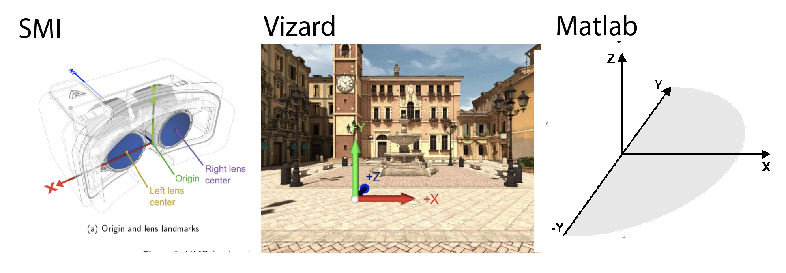

% Convert SMI data into Vizard coordinates
etData.cycEyeInHead_fr_XYZ(:,1) = -etData.cycEyeInHead_fr_XYZ(:,1);

Lets focus our attention on a single frame.  Not all frames of data are that interesting, so lets focus on a frame on which we know something interesing has happened.  For exmaple...lets se

Where the subject was looking at "ballRenderOn," for a single trial, after the ball was invisible for 0.5 seconds of movement. As a reminder, here's what a trial looked like...

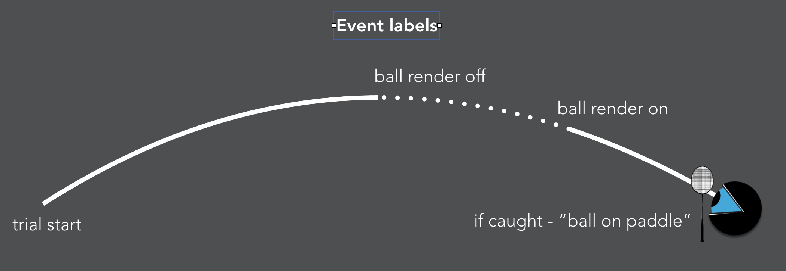

Lets get our events!

trialStart_tr = find(strcmp(etData.eventFlag_fr,'trialStart'));
ballRenderOn_tr = find(strcmp(etData.eventFlag_fr,'ballRenderOn'));
ballRenderOff_tr = find(strcmp(etData.eventFlag_fr,'ballRenderOn'));


Now, lets plot the EIH vector. I've added a set of axes to help you understand what's happening.

close all
figure(2)
cla
hold on
axis equal
grid on 
xlabel 'x'
ylabel 'y'
zlabel 'z'
xlim([-2,2])
ylim([-2 2])
zlim([-2 2])

fr = ballRenderOn_tr(1);


%% Draw the EIH signal
headPos_xyz = [0,0,0]

headPos_xyz =      0     0     0


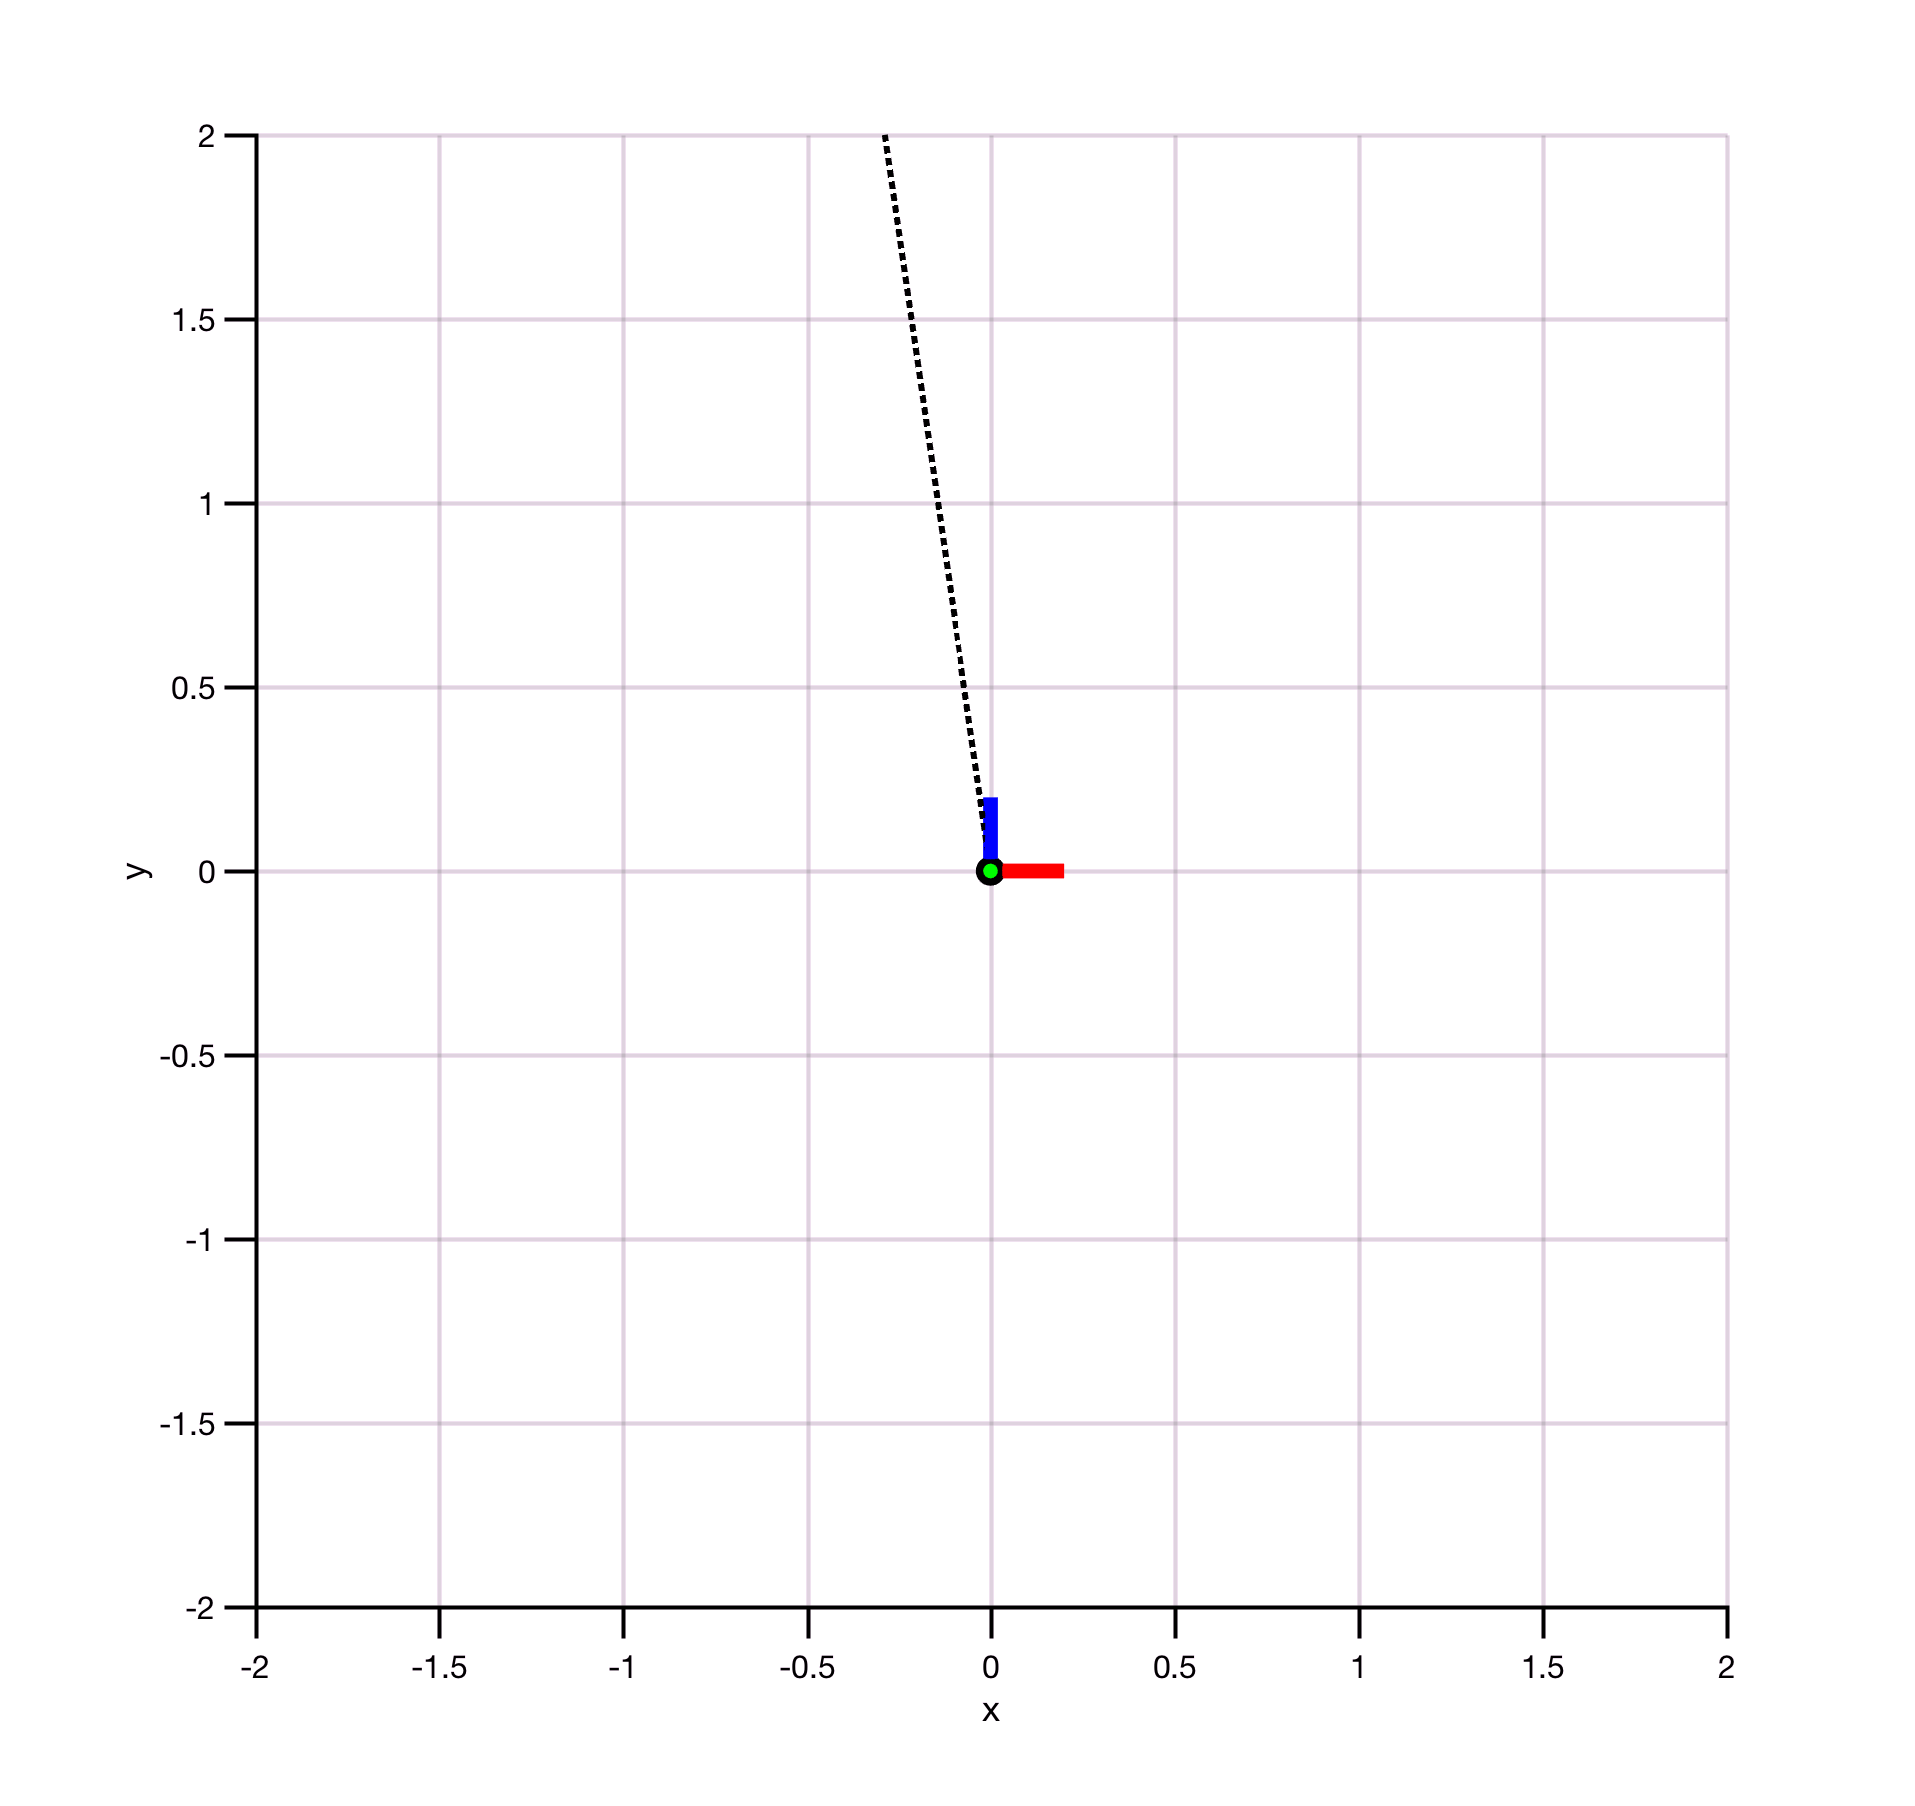

gazeLen = 10;
% Note that I scale the length of the vector by gazeLen (from the 1 meter normalized vector, 
% to a 10 meter vector).
gazeVecPos_xyz = etData.cycEyeInHead_fr_XYZ(fr,:)*gazeLen ;
line_xyz_pt = [gazeVecPos_xyz; headPos_xyz]';

plot3(line_xyz_pt(1,:), line_xyz_pt(3,:), line_xyz_pt(2,:),':k','linewidth',3)

headAxH = gdDrawAxisAtOrigin(eye(4),.2,.02);
set(2,'Units','Normalized','Position',[0.33 0.047 0.57 0.86]);

 # Convert EIH direction into a point along the subject's gaze-in-world vector.

To do this, we will multiply the gaze data by the virtual avatar's transformation matrix, which will translate/rotate the gaze vector to its location in front of the camera in the 3D world.

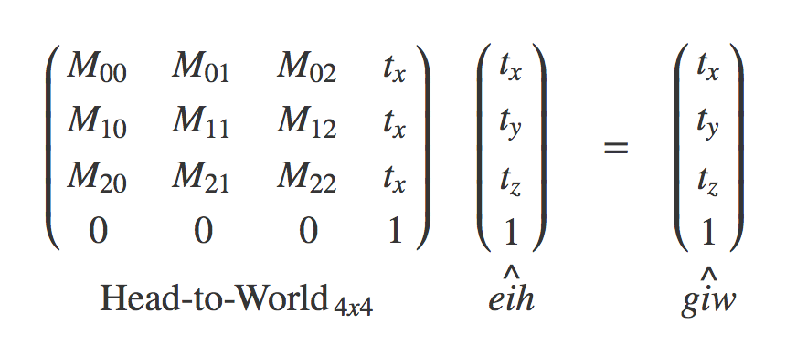

The cyclopean eye's transformation matrix was exported from the virtual reality software (Vizard) into the variable, "viewMat_4x4. 

Lets have a look at this matrix.

etData.viewMat_fr_4x4{fr}

ans =     0.9752    0.0480   -0.2159   -0.9456
   -0.0489    0.9988    0.0015    1.6859
    0.2157    0.0090    0.9764    0.0425
         0         0         0    1.0000


Compare that matrix to the output above. Sometimes, the matrix will be transposed during export, and require reconstruction. Assuming all the values are there, the important part is that the matrix has the correct orientaiton for matrix-vector multiplication, with the assumption column vectors, which is indicated by the last row being 0,0,0,1.  If those were instead in the last column, you can transpose the matrix like this: etData.viewMat_fr_4x4{fr}'.  ...but, things look good, so lets move on.

WHat about our EIH matrix? Is it in the column-vector format?

etData.cycEyeInHead_fr_XYZ(fr,:)

ans =    -0.1284   -0.0862    0.9880


No. It is a 3 element row vector, and we require homogenous coordinates in columns vector format. 

To fix, we add 1, and then  transpose the vector into column format with the ' operator.

[etData.cycEyeInHead_fr_XYZ(fr,:)*gazeLen  1]'

ans =    -1.2841
   -0.8620
    9.8797
    1.0000


Much better! Now, lets put this together to convert our single frame of data from EIH to GIW coordinates.

I'm also going to scale the length of the vector by gazeLen (from the 1 meter normalized vector, to a 10 meter vector).

fr = ballRenderOn_tr(1);
gazeLen = 10;
gazePointInWorld_xyzw = etData.viewMat_fr_4x4{fr} * [etData.cycEyeInHead_fr_XYZ(fr,:)*gazeLen  1]';

close all
figure(2)
cla
hold on
axis equal
%campos([2,2,2])
grid on 
xlabel 'x'
ylabel 'y'
zlabel 'z'
xlim([-2,2])
ylim([-2 2])
zlim([0 3])

origin = etData.viewMat_fr_4x4{fr}(1:3,4);
%campos([origin' + [-1,1,1]])%
%camtarget(origin)

%% Draw the EIH signal

headPos_xyz = etData.viewMat_fr_4x4{fr}(1:4,4)

headPos_xyz =    -0.9728
    1.7297
   -0.0523
    1.0000


headAxH = gdDrawAxisAtOrigin(etData.viewMat_fr_4x4{fr},.2,.02);

gaze_xyzw_pt = [gazePointInWorld_xyzw headPos_xyz];
gL = plot3(gaze_xyzw_pt(1,:), gaze_xyzw_pt(3,:), gaze_xyzw_pt(2,:),':k','linewidth',3)

gL =   Line (gaze vector) with properties:

              Color: [0 0 0]
          LineStyle: ':'
          LineWidth: 3
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-2.7596 -0.9728]
              YData: [8.8025 -0.0523]
              ZData: [6.0193 1.7297]

  Show all properties




ball_xyzw_pt = [etData.ballPos_fr_XYZ(fr,:)' headPos_xyz(1:3)];
bL =  plot3(ball_xyzw_pt(1,:), ball_xyzw_pt(3,:), ball_xyzw_pt(2,:),'r','linewidth',2)

bL =   Line (eye-to-ball vector) with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-2.6983 -0.9728]
              YData: [5.3340 -0.0523]
              ZData: [4.5836 1.7297]

  Show all properties


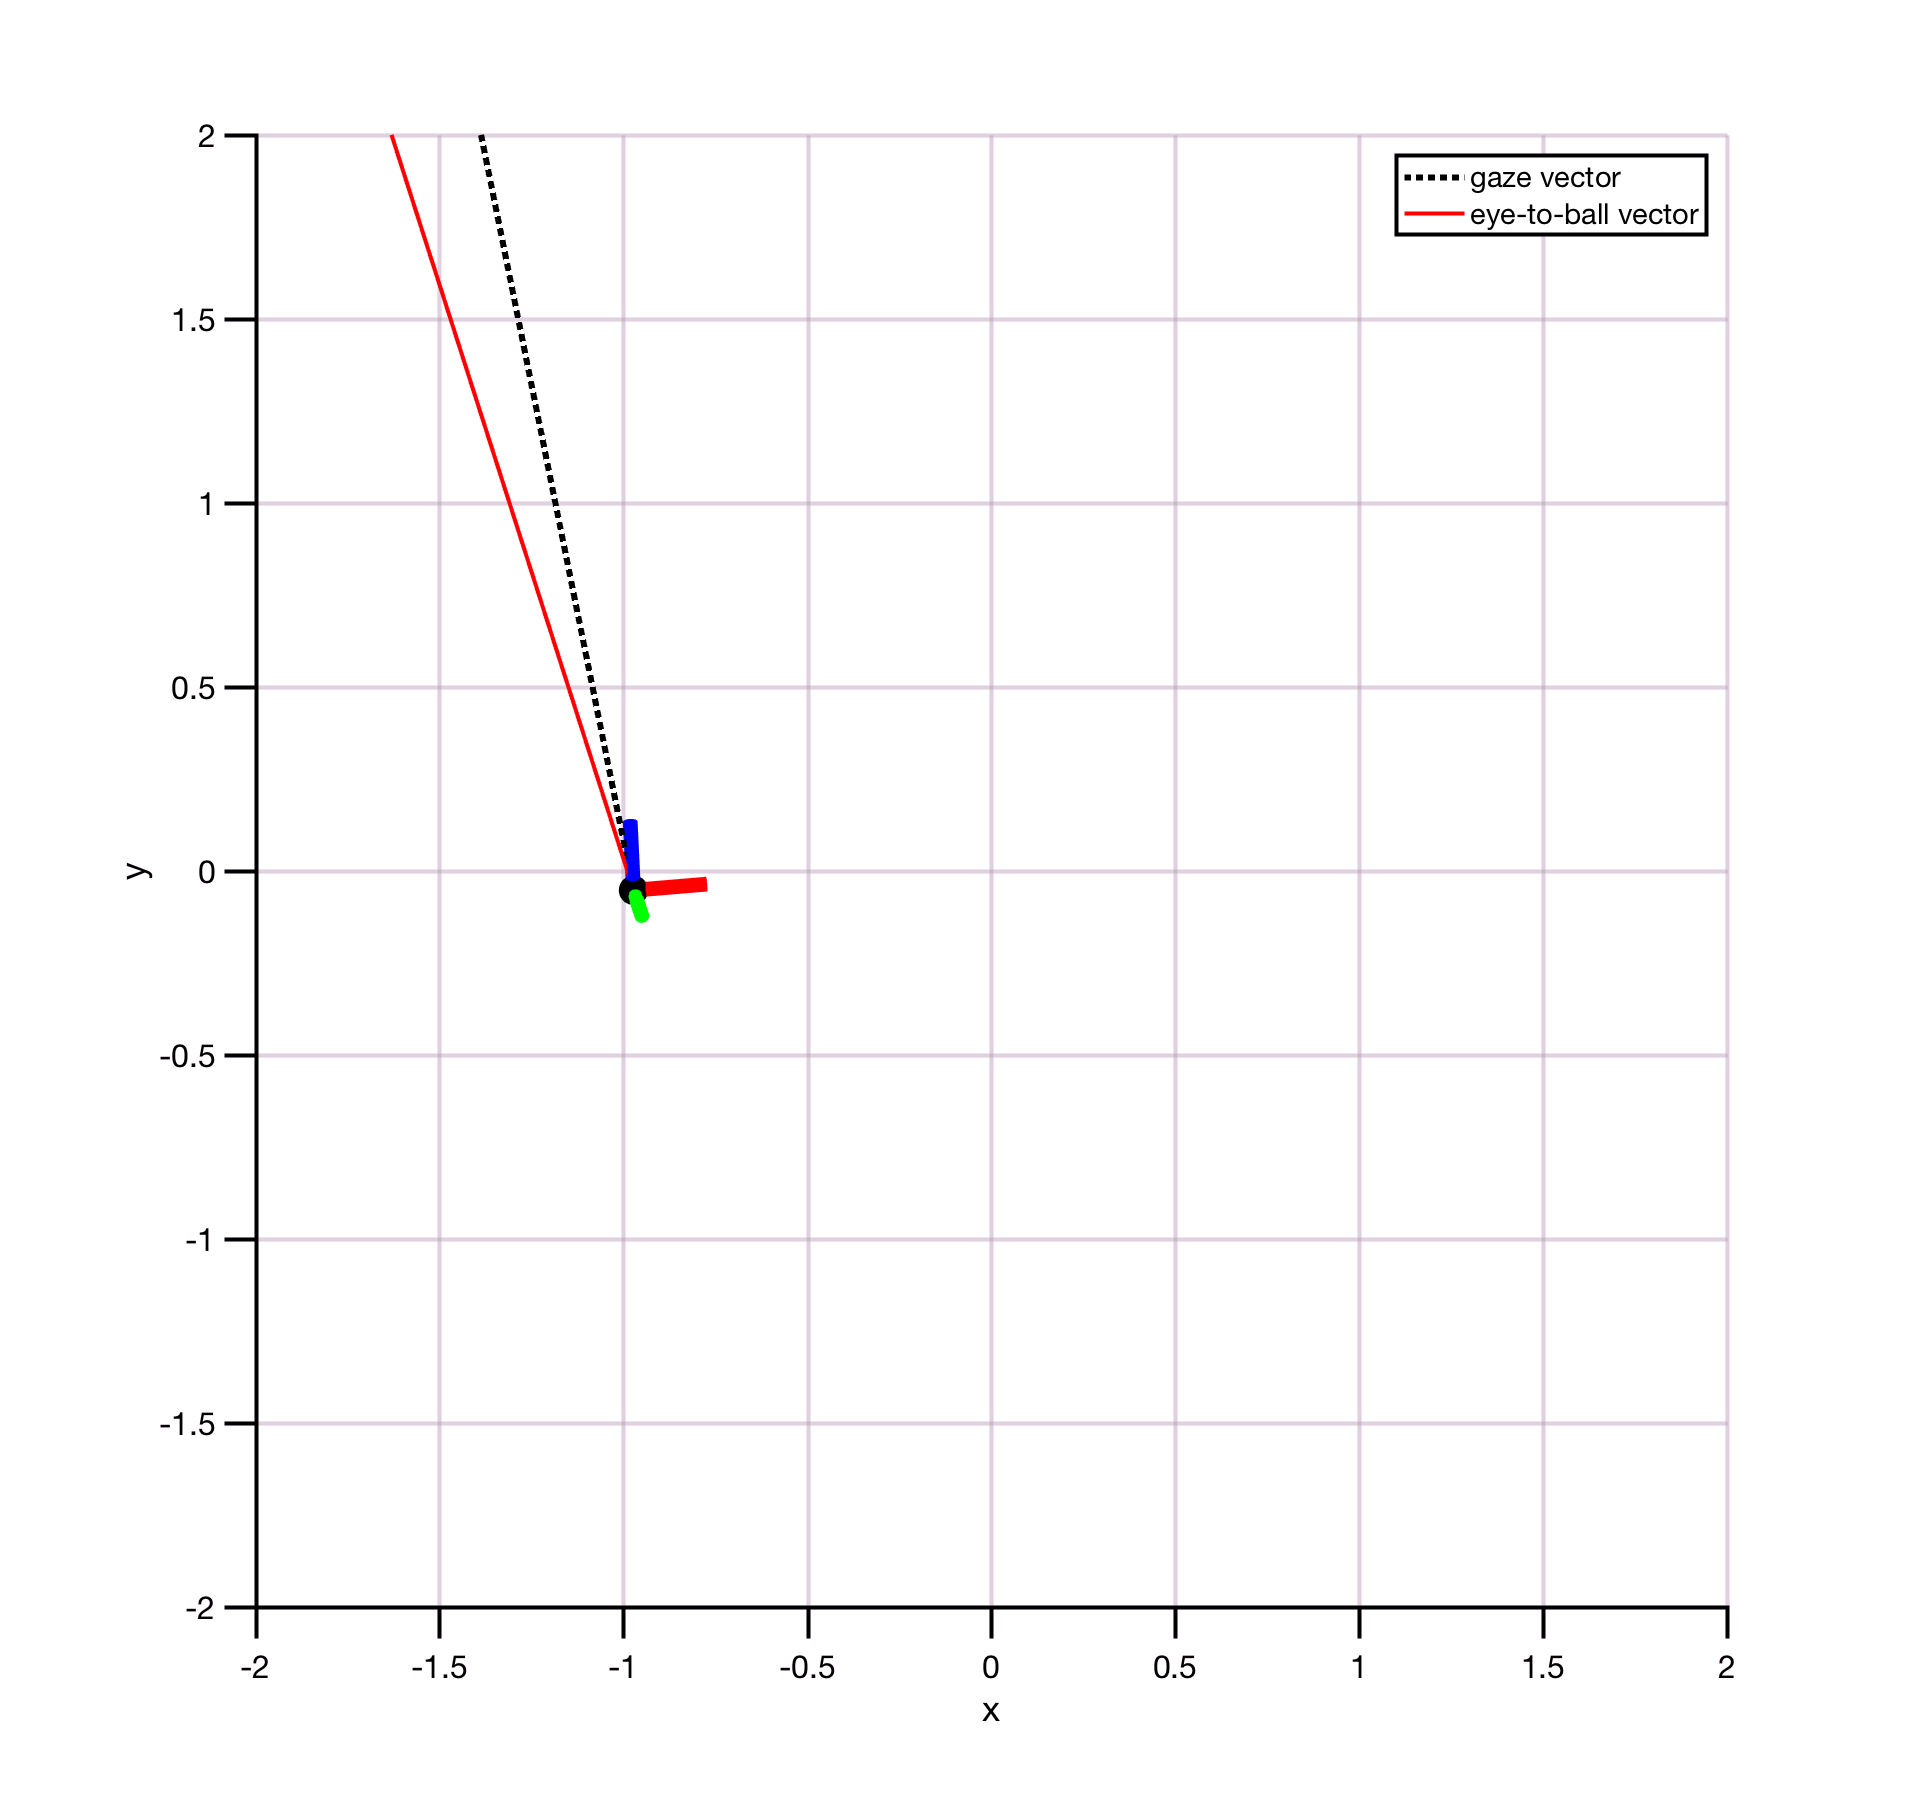


legend([gL,bL],{'gaze vector','eye-to-ball vector'})
set(2,'Units','Normalized','Position',[0.33 0.047 0.57 0.86]);

Excellent!